# Ordinary Differential Equations

## Introduction

### Definition of a Differential Equation			

A *differential equation is *an equation involving derivatives or differentials. The following are some examples of differential equations.

        **Example 1.** $(y\prime\prime)^2+3x=2(y\prime)^3$ where $y\prime=\frac{\mathrm dy}{\mathrm dx}$, $y\prime\prime=\frac{\mathrm d^2y}{\mathrm dx^2}$

        **Example 2.** $\frac{\mathrm dy}{\mathrm dx}+\frac{y}{x}=y^2$

        **Example 3.** $\frac{\mathrm d^2Q}{\mathrm dt^2}-3\frac{\mathrm dQ}{\mathrm dt}+2Q=4\sin2t$ or $\ddot Q-3\dot Q+2Q=4\sin2t$

        **Example 4. **$\frac{\mathrm dy}{\mathrm dx}=\frac{x+y}{x-y}$ or $(x+y)\mathrm dx+(y-x)\mathrm dy=0$

        **Example 5.** $\frac{\partial^2V}{\partial x^2}+\frac{\partial^2V}{\partial y^2}=0$

Equations such as those in Examples 1-4 involving only one independent variable are called *ordinary differential equations. *Equations such as that of Example 5 with two or more independent variables are called *partial differential equations *and are treated in Lecture 03.

### Order of a Differential Equation

An equation having a derivative of $n$th order but no higher is called an $n$th *order differential equation. *In Examples 1-5 above, the orders of the differential equations are 2,1, 2,1, 2, respectively.

### Arbitrary Constants

An arbitrary constant, often denoted by a letter at the beginning of the alphabet such as $A$*, *$B$*, *$C$*, *$c_1$, $c_2$, etc., may assume values independently of the variables involved. For example in $y= x^2+c_1 x+c_2$, $c_1$ and $c_2$ are arbitrary constants. 

The relation $y = A\mathrm e^{-4x +B}$ which can be written $y = A\mathrm e^B\mathrm e^{-4x}=C\mathrm e^{-4x}$ actually involves only one arbitrary constant. We shall always assume that the minimum number of constants is present, i.e. the arbitrary constants are *essential. *

### Solution of Differential Equation

A *solution *of a differential equation is a relation between the variables which is free of derivatives and which satisfies the differential equation identically.

        **Example 6.** $y=x^2+c_1x+c_2$ is a solution of $y\prime\prime =2$ since by substitution we obtain the identity $2=2$.

clear
syms x c1 c2
y = x^2 + c1*x + c2;
diff(y, x, 2)

$$ans = 2$$

A *general solution* of an $n$th order differential equation is one involving $n$ (essential) arbitrary constants.

        **Example 7.** Since $y=x^2+c_1x+c_2$ has two arbitrary constants and satifies the second order differential equation $y\prime\prime =2\,,$ it is a general solution of $y\prime\prime =2$.  

*A particular solution *is a solution obtained from the general solution by assigning specific values to the arbitrary constants. 

        **Example 8.** Since $y=x^2-3x+2$ is a particular solution of $y\prime\prime =2$, and is obtained from the general solution $y=x^2+c_1x+c_2$ by putting $c_1=-3$ and $c_2=2$.

y = subs(y, {c1, c2}, {-3, 2})

$$y = x^{2}-3\,x+2$$

A *singular solution *is a solution which cannot be obtained from the general solution by specifying values of the arbitrary constants. 					

        **Example 9.** The general solution of $y=xy\prime-y\prime^2$ is $y=cx-c^2$*. *However, as seen by substitution another solution is $y=\frac{x^2}{4}$ which cannot be obtained from the general solution for any constant $c$. This second solution is a singular solution.

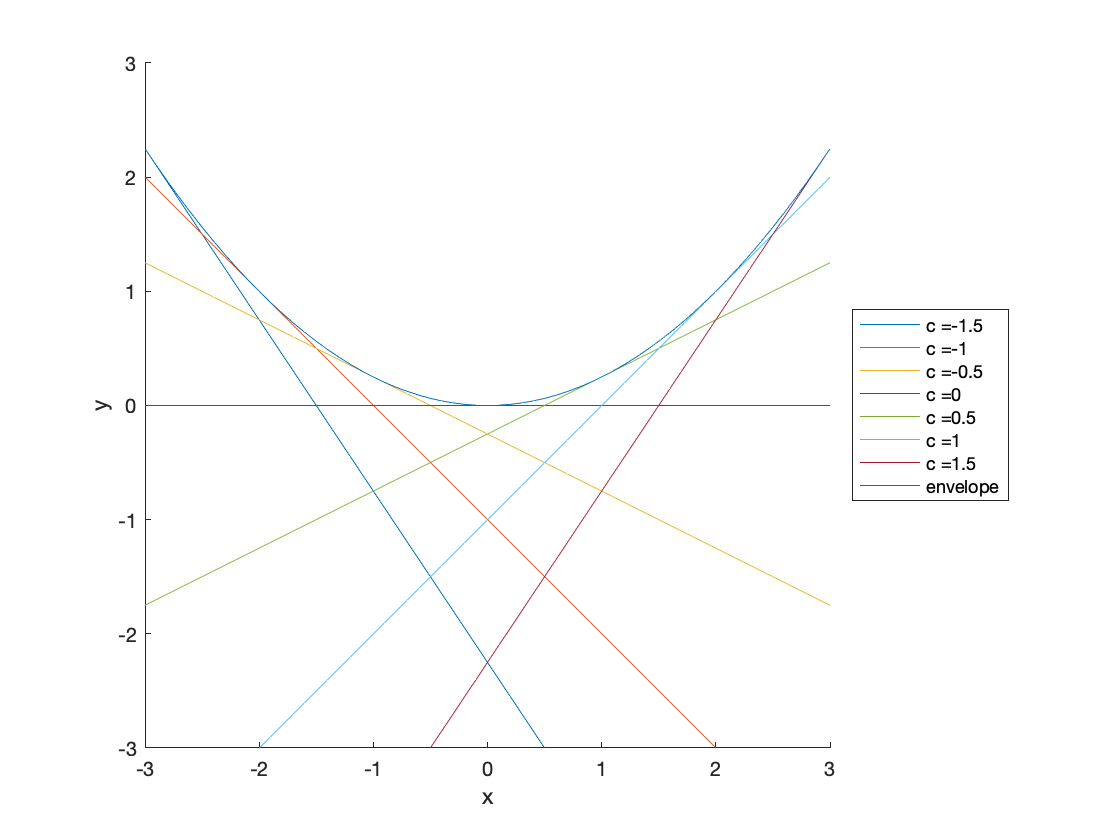

clear
figure
x = -3:0.1:3;
y = x.^2/4;
hold on
legends = {};
for c = -1.5:0.5:1.5
    plot(x, c*x-c^2)
    legends{end+1} = strcat('c = ', num2str(c));
end
plot(x,y); xlabel('x'); ylabel('y')
legends{end+1} = 'envelope';
legend(legends, 'Location', 'eastoutside')
axis equal
axis([-3 3 -3 3])

It is seen that $y=cx-c^2$ represents a family of straight lines tangent to the parabola $y=\frac{x^2}{4}$*. *The parabola is the *envelope *of the family of straight lines.

The envelope of a family of curves $G(x, y, c)=0$, if it exists, can be found by solving simultaneously the equations $\frac{\partial G}{\partial c} = 0$ and $G=0$. In this example $G(x,y, c) = y-cx+c^2$ and $\frac{\partial G}{\partial c} = -x+2c$. Solving simultaneously $-x+2c=0$ and $y-cx+c^2=0$, we find $x=2c$*, *$y=c^2$ or $y=\frac{x^2}{4}$*. *

### Differential Equation of a Family of Curves

A general solution of an $n$th order differential equation has $n$ arbitrary constants (or parameters) and represents geometrically an $n$* parameter family of curves. *Conversely a relation with $n$ arbitrary constants [sometimes called a *primitive] *has associated with it a differential equation of order $n$ [of which it is a general solution] called the *differential equation of the family. *This differential equation is obtained by differentiating the primitive $n$ times and then eliminating the $n$ arbitrary constants among the $n + 1$ resulting equations.

        **Example 10.** Obtain the differential equation for the one parameter family of curves $y=cx^3$.

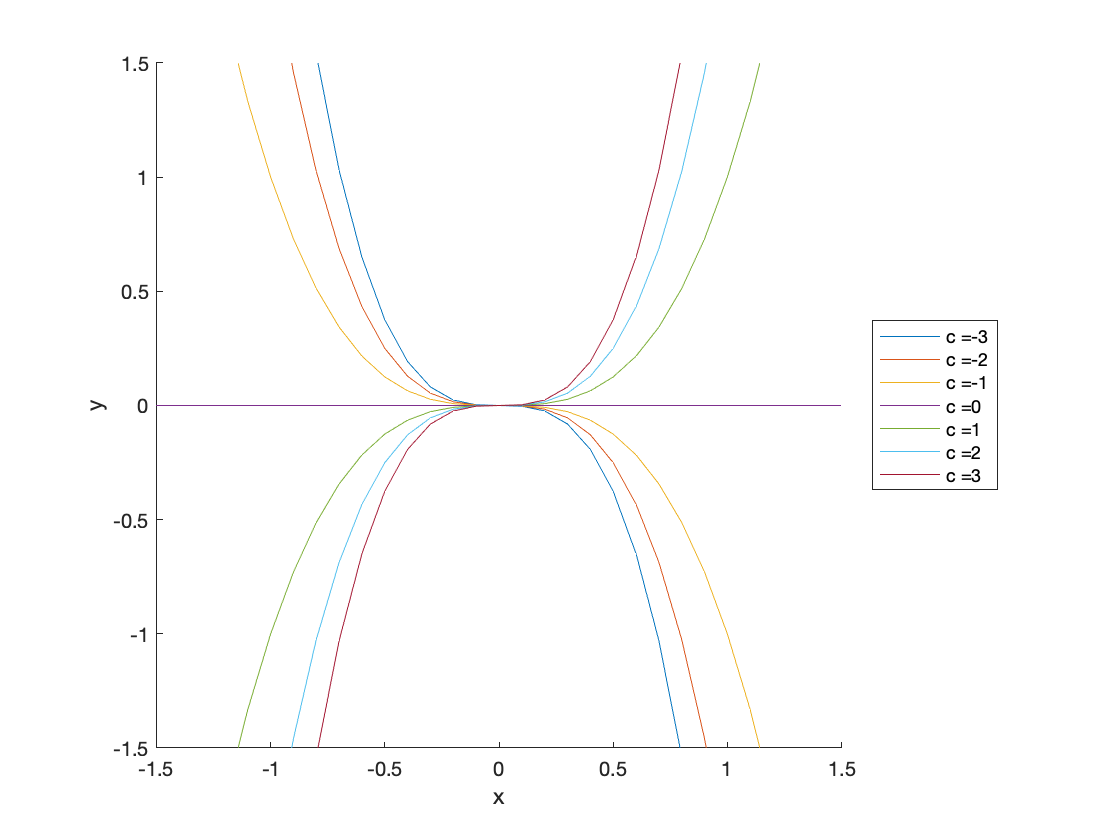

clear
figure
x = -1.5:0.1:1.5;
xlabel('x'); ylabel('y'); hold on
legends = {};
for c = -3:3
    plot(x, c*x.^3)
    legends{end+1} = strcat('c = ', num2str(c));
end
legend(legends, 'Location', 'eastoutside')
axis equal
axis([-1.5 1.5 -1.5 1.5])

From $y = cx^3$ we have $\frac{\mathrm dy}{\mathrm dx} = 3cx^2$. Then since $c = \frac{y}{x^3}$*, *the required differential equation of the family is

$\frac{\mathrm dy}{\mathrm dx}=3\left(\frac{y}{x^3}\right)x^2$ or $\frac{\mathrm dy}{\mathrm dx}=\frac{3y}{x}$

## Special First Order Equations and Solutions

Any first order differential equation can be put into the form

$\frac{\mathrm dy}{\mathrm dx}=f(x,y$ or $M(x,y)\mathrm dx+N(x,y)\mathrm dy=0$

and the general solution of such an equation contains one arbitrary constant. Many special devices are available for finding general solutions of various types of first order differential equations.

### Separation of variables

#### Standard form


$$f_1(x)g_1(y)\mathrm dx+f_2(x)g_2(y)\mathrm dy=0$$


#### Method

Divide by $g_1(y)f_2(x)\neq0$ and integrate to obtain


$$\int\frac{f_1(x)}{g_1(x)}\,\mathrm dx+\int\frac{g_2(y)}{f_2(y)}\,\mathrm dy=c$$


        **Example 11.** Find the particular solution of $(4x+xy^2)\mathrm dx+(y+x^2y)\mathrm dy=0$ for which $y(1)=2$.

The equation can be written as $x(4+y^2)\mathrm dx+y(1+x^2)\mathrm dy=0$ or


$$\frac{x}{1+x^2}\mathrm dx+\frac{y}{4+y^2}\mathrm dy=0$$


Integrating,

clear
syms x y c1 real
eq = int(x/(1+x^2), x) + int(y/(4+y^2), y) == c1

$$eq = \frac{\log\left(x^{2}+1\right)}{2}+\frac{\log\left(y^{2}+4\right)}{2}=c_{1}$$

thus,


$$\frac{1}{2}\ln(x^2+1)+\frac{1}{2}\ln(y^2+4)=c_1$$


eq = combine(2*eq, 'log')

$$eq = \log\left(\left(x^{2}+1\right)\,\left(y^{2}+4\right)\right)=2\,c_{1}$$

eq = exp(lhs(eq)) == exp(rhs(eq))

$$eq = \left(x^{2}+1\right)\,\left(y^{2}+4\right)={\mathrm{e}}^{2\,c_{1}}$$

and we find the general solution


$$(x^2+1)(y^2+4)=\mathrm e^{2c_1}=c$$


For the particular solution where $y(1)=2$, i.e. $y=2$ when $x=1$, put $x=1$, $y=2$ in $(x^2+1)(y^2+4)=c$

c = subs(eq, {x,y}, {1, 2})

$$c = 16={\mathrm{e}}^{2\,c_{1}}$$

Thus $(x^2+1)(y^2+4)=16$.

### Exact equation

#### Standard form

$M(x,y)\mathrm dx+N(x,y)\mathrm dy=0$ where $\frac{\partial M}{\partial y}=\frac{\partial N}{\partial x}$

#### Method

The equation can be written as $M(x,y)\mathrm dx+N(x,y)\mathrm dy=\mathrm dU(x,y)=0$ where $\mathrm dU$ is an exact differential. Thus the solution is $U(x,y)=c$ or equivalently


$$\int M(x,y)\mathrm dx+\int\left(N(x,y)-\frac{\partial}{\partial y}\int M(x,y)\mathrm dx\right)\mathrm dy=c$$


        **Example 12.** Find the general solution of $(3x^2+y\cos x)\mathrm dx+(\sin x-4y^3)\mathrm dy=0$.

Here $M(x,y)=3x^2+y\cos x$, $N(x,y)=\sin x-4y^3$ so that $\frac{\partial M}{\partial y}=\cos x=\frac{\partial N}{\partial x}$ and the equation is exact.

**Solution 1 [Grouping of terms by inspection].** Write the equation as


$$3x^2\mathrm dx+(y\cos x\mathrm dx+\sin x\mathrm dy)-4y^3\mathrm dy=0$$



$$\mathrm d(x^3)+\mathrm d(y\sin x)-\mathrm d(y^4)=0$$



$$\mathrm d(x^3+y\sin x-y^4)=0$$


Then on integrating, $x^3+y\sin x-y^4=c$.

**Solution 2 [Direct method].** Since $M(m,y)\mathrm dx+N(x,y)\mathrm dy=\mathrm dU(x,y)$ an exact differential equation is and $\mathrm dU=\frac{\partial U}{\partial x}\mathrm dx+\frac{\partial U}{\partial y}\mathrm dy$, we must have

$\frac{\partial U}{\partial x}=M(x,y)$ and $\frac{\partial U}{\partial y}=N(x,y)$

or $\frac{\partial U}{\partial x}=3x^2+y\cos x$, $\frac{\partial U}{\partial y}=\sin x-4y^3$.

Integrating the first equation partially with respect to $x$,

clear
syms x y real
M = 3*x^2+y*cos(x);
N = sin(x)-4*y^3;
U = int(M, x)

$$U = y\,\sin\left(x\right)+x^{3}$$

we have $U(x,y) = y\sin x + x^3+F(y)$  where $F(y)$ is the constant of integration which may depend on $y$.

Substituting this result in $\frac{\partial U}{\partial y}$,

syms F(y)
eq = diff(U + F(y), y) - N == 0

$$eq = \frac{\partial }{\partial y}F\left(y\right)+4\,y^{3}=0$$

we find $F\prime(y)=-4y^3$, so that

syms c1
F(y) = int(-4*y^3, y) + c1

$$F(y) = c_{1}-y^{4}$$

$F(y)=c_1-y^4$. Then from the expression of $U$,

U = U + F(y)

$$U = c_{1}+y\,\sin\left(x\right)+x^{3}-y^{4}$$


$$U(x,y) = c_1 +y\,\sin x+x^3 -y^4$$


Thus $M(x,y)\mathrm dx+N(x,y)\mathrm dy=\mathrm dU(x,y)=0=\mathrm d(c_1 +y\,\sin x+x^3 -y^4) =0$ from which we must have


$$x^3+y\sin x-y^4=c$$


**Solution 3 [Formula].**

syms x y c real
M = 3*x^2+y*cos(x);
N = sin(x)-4*y^3;
sol = int(M, x) + int(N - diff(int(M, x), y), y) == c

$$sol = y\,\sin\left(x\right)+x^{3}-y^{4}=c$$

### Integrating Factors

#### Standard Form

$M(x,y)\mathrm dx+N(x,y)\mathrm dy=0$ where $\frac{\partial M}{\partial y}\neq\frac{\partial N}{\partial x}$

#### Method

The equation can be written as an exact differential equation


$$\mu(x,y)M(x,y)\mathrm dx+\mu(x,y)N(x,y)\mathrm dy=0$$


where $\mu(x,y)$ is an appropriate *integrating factor* so that $\frac{\partial\mu(x,y) M(x,y)}{\partial y}=\frac{\partial\mu(x,y) N(x,y)}{\partial x}$ and the equation is exact.

The following combinations are often useful in finding integrating factors.

- 
$$\frac{x\mathrm dy-y\mathrm dx}{x^2}=\mathrm d\left(\frac{y}{x}\right)$$


-  
$$\frac{x\mathrm dy-y\mathrm dx}{y^2}=-\mathrm d\left(\frac{x}{y}\right)$$


- 
$$\frac{x\mathrm dy-y\mathrm dx}{x^2+y^2}=\mathrm d\left(\tan^{-1}\frac{y}{x}\right)$$


- 
$$\frac{x\mathrm dy-y\mathrm dx}{x^2-y^2}=\frac{1}{2}\mathrm d\left(\ln\frac{x-y}{x+y}\right)$$


- 
$$\frac{x\mathrm dy+y\mathrm dx}{x^2+y^2}=\frac{1}{2}\mathrm d\left(\ln\left(x^2+y^2\right)\right)$$


        **Theorem 1.** If $M(x,y)\mathrm dx+N(x,y)\mathrm dy=0$ has an integrating factor $\mu(x)$ which depends only on $x$, then $\mu(x)=\mathrm e^{\int f(x)\mathrm dx}$ where $f(x)=\frac{M_y-N_x}{N}$, $M_y=\frac{\partial M}{\partial y}$, and $N_x=\frac{\partial N}{\partial x}$.

        **Demonstration**. By hypothesis, $\mu(x)M(x,y)\mathrm dx+\mu(x)N(x,y)\mathrm dy=0$ is exact. Then


$$\frac{\partial\mu(x) M(x,y)}{\partial y}=\frac{\partial\mu(x) N(x,y)}{\partial x}$$


Since $\mu$ depends only on $x$ this can be written 

$\mu(x)\frac{\partial M(x,y)}{\partial y}=\mu(x)\frac{\partial N(x,y)}{\partial x}+N(x,y)\frac{\mathrm d\mu}{\mathrm dx }$ or $N(x,y)\frac{\mathrm d\mu}{\mathrm dx}=\mu(x)\left(\frac{\partial M(x,y)}{\partial y}-\frac{\partial N(x,y)}{\partial x}\right)$

Thus $\frac{\mathrm d\mu}{\mu}=\left(\frac{M_y-N_x}{N}\right)\mathrm dx=f(x)\mathrm dx$ and so $\ln\mu=\int f(x)\mathrm dx$ or $\mu(x)=\mathrm e^{\int f(x)\mathrm dx}$.

An analogous theorem exist if the integrating factor depends only on $y$.

        **Example 13.** Find the general solution of $(3xy^2+2y)\mathrm dx+(2x^2y+x)\mathrm dy=0$.

clear
syms x y real
M = 3*x*y^2+2*y;
N = 2*x^2*y+x;
My = diff(M, y);
Nx = diff(N, x);
f(x) = (My-Nx)/N

$$f(x) = \frac{2\,x\,y+1}{2\,y\,x^{2}+x}$$

f(x) = simplify(f(x))

$$f(x) = \frac{1}{x}$$

$f(x)$ depends only on $x$. Thus

mu(x) = exp(int(f(x), x))

$$mu(x) = x$$

$\mu(x)=x$ is an integrating factor. Using the formula of an exact equation

syms c real
M = mu(x)*M;
N = mu(x)*N;
sol = int(M, x) + int(N - diff(int(M, x), y), y) == c

$$sol = x^{2}\,y\,\left(x\,y+1\right)=c$$

sol = expand(sol)

$$sol = x^{3}\,y^{2}+x^{2}\,y=c$$

### Linear Equation

#### Standard Form


$$\frac{\mathrm dy}{\mathrm dx}+P(x)y=Q(x)$$


#### Method

An integrating factor is given by $\mu(x)=\mathrm e^{\int P(x)\mathrm dx}$ and the equation can then be written $\frac{\mathrm d\mu(x)y(x)}{\mathrm dx}=\mu(x)Q(x)$ with solution $\mu(x)y=\int\mu(x)Q(x)\mathrm dx+c$ or $y(x)=\mathrm e^{-\int P(x)\mathrm dx}\int Q(x)e^{\int P(x)\mathrm dx}\mathrm dx+c\mathrm e^{-\int P(x)\mathrm dx}$

Write the equation as


$$\left(P(x)y-Q(x)\right)\mathrm dx+\mathrm dy=0$$


Then $M=P(x)y-Q(x)$, $N=1$, $M_y=P(x)$, $N_x=0$

Since $\frac{M_y-N_x}{N}=\frac{P(x)-0}{1}=P(x)$ depends only on $x$, we see from theorem 1 that $\mathrm e^{\int P(x)\mathrm dx}$ is an integrating factor. Multiplying by this factor, the equation becomes


$$\mathrm e^{\int P(x)\mathrm dx}\left(\frac{\mathrm dy}{\mathrm dx}+Py\right)=Q(x)\mathrm e^{\int P(x)\mathrm dx}$$


which can be written as


$$\frac{\mathrm d}{\mathrm dx}\left(\mathrm e^{\int P(x)\mathrm dx}y\right)=Q(x)\mathrm e^{\int P(x)\mathrm dx}$$


Then on integrating we have


$$\mathrm e^{\int P(x)\mathrm dx}y=\int Q(x)\mathrm e^{\int P(x)\mathrm dx}\mathrm dx+c$$


or


$$y(x)=\mathrm e^{-\int P(x)\mathrm dx}\int Q(x)e^{\int P(x)\mathrm dx}\mathrm dx+c\mathrm e^{-\int P(x)\mathrm dx}$$


        **Example 14.** Solve $x\frac{\mathrm dy}{\mathrm dx}-2y=x^3\cos 4x$.

Write the equation as $\frac{\mathrm dy}{\mathrm dx}-\frac{2}{x}y=x^2\cos 4x$, a linear equation of the form $\frac{\mathrm dy}{\mathrm dx}+P(x)y=Q(x)$ with $P=-\frac{2}{x}$, $Q=x^2\cos 4x$. An integration factor is

clear
syms x y real
P = -2/x;
Q = x^2*cos(4*x);
mu = exp(int(P, x))

$$mu = \frac{1}{x^{2}}$$

syms c real
sol = 1/mu*int(Q*mu, x)+c/mu

$$sol = \frac{x^{2}\,\sin\left(4\,x\right)}{4}+c\,x^{2}$$

### Homogeneous Equation

#### Standard Form


$$\frac{\mathrm dy}{\mathrm dx}=F\left(\frac{y}{x}\right)$$


#### Method

Let $\frac{y}{x}=v$ or $y=vx$, and the equation becomes $v+x\frac{\mathrm dv}{\mathrm dx}=F(v)$ or $x\mathrm dv+\left(F(v)-v\right)\mathrm dx=0$ with is a separable equation and has the solution


$$\ln x=\int\frac{1}{F(v)-v}\mathrm dv +c$$


where $v=\frac{y}{x}$.

        **Example 15.** Solve $\left(2x^3+y^3\right)\mathrm dx-3xy^2\mathrm dy=0$.

Write as $\frac{\mathrm dy}{\mathrm dx}=\frac{2x^3+y^3}{3xy^2}$. The right side is seen to be a function of $\frac{y}{x}$ either by writing it as


$$\frac{2x^3}{3xy^2}+\frac{y^3}{3xy^2}=\frac{2}{3\left(\frac{y}{x}\right)^2}+\frac{1}{3}\left(\frac{y}{x}\right)$$


or by letting $y=vx$ and showing that the right side depends only on $v$, i.e.

clear
syms x y v real
F = (2*x^3+y^3)/(3*x*y^2);
F(v) = simplify(subs(F, y, v*x))

$$F(v) = \frac{v^{3}+2}{3\,v^{2}}$$

Thus the equation is homogeneous.

syms c1 c
sol = x == simplify(exp(int(1/(F(v)-v), v) + c1))

$$sol = x=\frac{{\mathrm{e}}^{c_{1}}}{\sqrt{v^{3}-1}}$$

From $y=vx$, we obtain the required solution

sol = simplify(subs(lhs(sol^2 * (v^3-1)), v, y/x)) == c

$$sol = -\frac{x^{3}-y^{3}}{x}=c$$

### Bernoulli's Equation

#### Standard Form

$\frac{\mathrm dy}{\mathrm dx}+P(x)y=Q(x)y^n$, $n\notin\left\{0,1\right\}$

#### Method

Letting $v=y^{1-n}$, the equation reduces to a linear one with solution


$$v\mathrm e^{(1-n)\int P(x)\mathrm dx}=(1-n)\int Q(x)\mathrm e^{(1-n)\int P(x)\mathrm dx}+c$$


        **Example 16.** Solve $x\frac{\mathrm dy}{\mathrm dx}+y=xy^3$.

The equation written as $\frac{\mathrm dy}{\mathrm dx}+\frac{y}{x}=y^3$ is a Bernoulli equation with $P(x)=\frac{1}{x}$, $Q(x)=1$, $n=3$. Making the tranformation $y^{1-3}=y^{-2}=v$, we find the solution

clear
syms x y c real
P = 1/x;
Q = 1;
n = 3;
v = y^(1-n);
mu = exp((1-n)*int(P, x));
sol = v == (1-n) / mu * int(Q*mu, x) + c / mu

$$sol = \frac{1}{y^{2}}=c\,x^{2}+2\,x$$

### Equation solvable for $y$

#### Standard Form

$y=g(x,p)$ where $p=y\prime$

#### Method

Differentiate both sides of the equation with respect to $x$ to obtain

$\frac{\mathrm dy}{\mathrm dx}=\frac{\mathrm dg}{\mathrm dx}=\frac{\partial g}{\partial x}+\frac{\partial g}{\partial p}\frac{\mathrm dp}{\mathrm dx}$ or $p=\frac{\partial g}{\partial x}+\frac{\partial g}{\partial p}\frac{\mathrm dp}{\mathrm dx}$

Then solve this last equation to obtain $G(x,p,c)=0$. The required solution is obtained by eliminating $p$ between $G(x,p,c)=0$ and $y=g(x,p)$.

An analogous method exists if the equation is solvable for $x$.

        **Example 17.** Solve $xp^2+2px-y=0$ where $p=y\prime$.

The equation can be solved explicitly for $y$, i.e. $y=xp^2+2px$ and applying the method yields

clear
syms x p real
syms p(x)
g(x) = x*p(x)^2 + 2*p(x)*x;
eq = p == diff(g(x), x)

$$eq(x) = p\left(x\right)=2\,x\,p\left(x\right)\,\frac{\partial }{\partial x}p\left(x\right)+2\,x\,\frac{\partial }{\partial x}p\left(x\right)+{p\left(x\right)}^{2}+2\,p\left(x\right)$$

simplify(eq)

$$ans(x) = 2\,x\,\frac{\partial }{\partial x}p\left(x\right)+p\left(x\right)=0\vee p\left(x\right)=-1$$

Case 1. $p\neq -1$, we solve the separable equation $2x\mathrm dp + p\mathrm dx=0$

syms p c1 real
sol = int(1/p, p)+int(1/(2*x), x) == c1

$$sol = \log\left(p\right)+\frac{\log\left(x\right)}{2}=c_{1}$$

syms c real
sol = simplify(exp(lhs(2*sol))) == c

$$sol = p^{2}\,x=c$$

We can now eliminate $p$ 

syms y
eliminate([sol, y==x*p^2+2*p*x], p) == 0

$$ans = c^{2}-2\,c\,y-4\,x\,c+y^{2}=0$$

Case 2. $p+1=0$.

syms y
subs(y==x*p^2+2*p*x, p , -1)

$$ans = y=-x$$

This is a singular solution.